# State Signal Preperation File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 30/05/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Manipulation/',exportName);

Set Prepared data export path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

**Set Directories & Load Data**

Load Signal data

% use your default user path to create the filename and path
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'))
load 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
% load 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';

% rename the variables with underscores instead of spaces
SIG_PlotNames = strrep(SIG_aligned_dataTable.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
SIG_PlotNames = strrep(SIG_PlotNames, 'TR', '');


## 2. SIGNAL Data Manipulation

- CPI lag by 1 month

- Money supply lag by 1 month

- GDP lag by 3 months

- 'OECD' Leading indicator by 6 months

### 2.1 Lag CPI and Money supply Indicators by 1 month to account for delay in information.

% varaibles to lag: SACPIYOY_Index & SAMYM3Y_Index
% Lag {'SACPIYOY_Index', 'SAMYM3Y_Index'} by 1 timestamp
lagged_SACPIYOY_Index = [NaN; SIG_aligned_dataTable.SACPIYOY_Index(1:end-1)];
lagged_SAMYM3Y_Index = [NaN; SIG_aligned_dataTable.SAMYM3Y_Index(1:end-1)];

GDP (3 mnth)

% Lag GDP {SAGDP_M_INTERPOLATED} by 3 months
lagged_SAGDP_Index = [NaN(3, 1); SIG_aligned_dataTable.SAGDP_M_INTERPOLATED(1:end-3)];

'OEZAKLAP_Index' (6 mnth)

% Lag GDP {SAGDP_M_INTERPOLATED} by 3 months
lagged_OEZAKLAP_Index = [NaN(6, 1); SIG_aligned_dataTable.OEZAKLAP_Index(1:end-6)];

### 2.2 Replace original vars with lagged vars

% Add the lagged variables as columns to SIG_aligned_dataTable
SIG_aligned_dataTable.lagged_SACPIYOY_Index = lagged_SACPIYOY_Index;
SIG_aligned_dataTable.lagged_SAMYM3Y_Index = lagged_SAMYM3Y_Index;
SIG_aligned_dataTable.lagged_SAGDP_Index = lagged_SAGDP_Index;
SIG_aligned_dataTable.lagged_OEZAKLAP_Index = lagged_OEZAKLAP_Index;

% move original cols to end of TT
SIG_aligned_dataTable = movevars(SIG_aligned_dataTable,{'SACPIYOY_Index', 'SAMYM3Y_Index', 'SAGDP_M_INTERPOLATED','OEZAKLAP_Index'},'After',width(SIG_aligned_dataTable));

New timetable with only lagged values

SIG_prep_TT = SIG_aligned_dataTable(:, setdiff(SIG_aligned_dataTable.Properties.VariableNames, {'SACPIYOY_Index', 'SAMYM3Y_Index', 'SAGDP_M_INTERPOLATED','OEZAKLAP_Index'}))

SIG_prep_TT = 277×13 timetable
       Dates       JALSHTR_Index    JIBA3M_Index    JPEIGLBL_Index    NAPMPMI_Index    SAVIT40_Index    SPX_Index    US0003M_Index    USDZAR_Curncy    VIX_Index    lagged_OEZAKLAP_Index    lagged_SACPIYOY_Index    lagged_SAGDP_Index    lagged_SAMYM3Y_Index
    ___________    _____________    ____________    ______________    _____________    _____________    _________    _____________    _____________    _________    _____________________    _____________________    __________________    _________

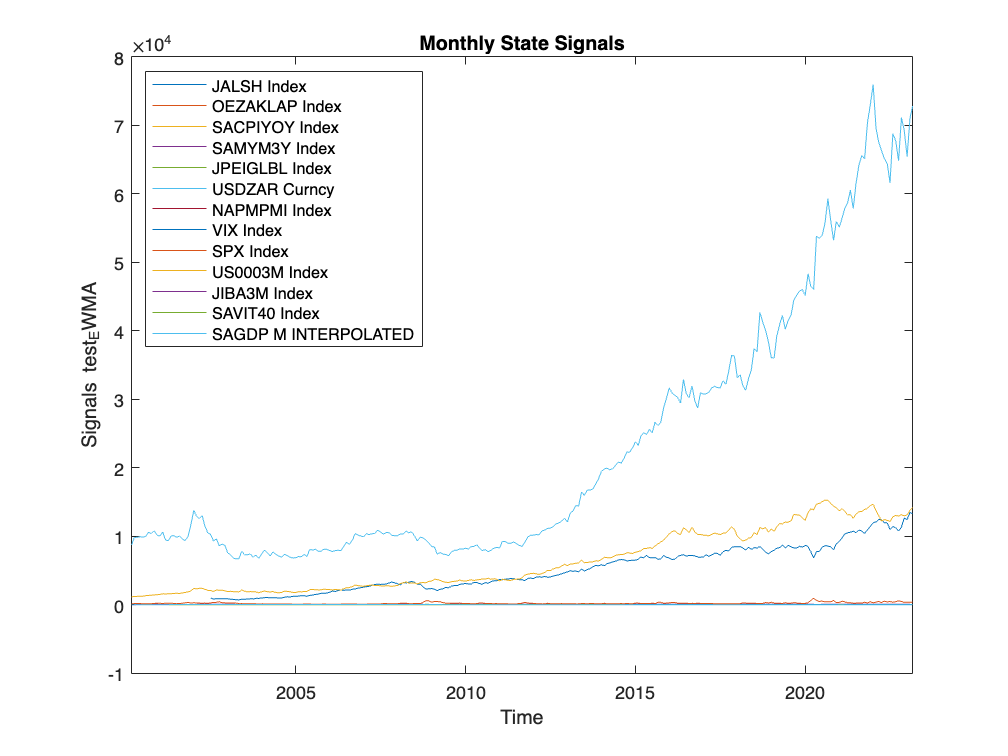

% Plot all asset normalised TRIs on a single plot
plot(SIG_prep_TT.Dates, table2array(SIG_prep_TT));
ylabel("Signals test_EWMA");
xlabel("Time");
title("Monthly State Signals");
% include the legend
legend(SIG_PlotNames,Location="northwest");
SIG_prep_TT_plot = gca;
hold off;

#### **2.2.1 Remove NA:** 

We currently have 23 yrs of data, however, 15 yrs of historical data should suffice, therefore we can drop the dates prior to the initial existance of all indices:

[countNans,idx] = max(sum(isnan(SIG_prep_TT{:,:}),1));
rmmissingProxy =  SIG_prep_TT.Properties.VariableNames{idx};
SIG_prep_TT = rmmissing(SIG_prep_TT,"DataVariables",rmmissingProxy)

SIG_prep_TT = 190×13 timetable
       Dates       JALSHTR_Index    JIBA3M_Index    JPEIGLBL_Index    NAPMPMI_Index    SAVIT40_Index    SPX_Index    US0003M_Index    USDZAR_Curncy    VIX_Index    lagged_OEZAKLAP_Index    lagged_SACPIYOY_Index    lagged_SAGDP_Index    lagged_SAMYM3Y_Index
    ___________    _____________    ____________    ______________    _____________    _____________    _________    _____________    _____________    _________    _____________________    _____________________    __________________    _________

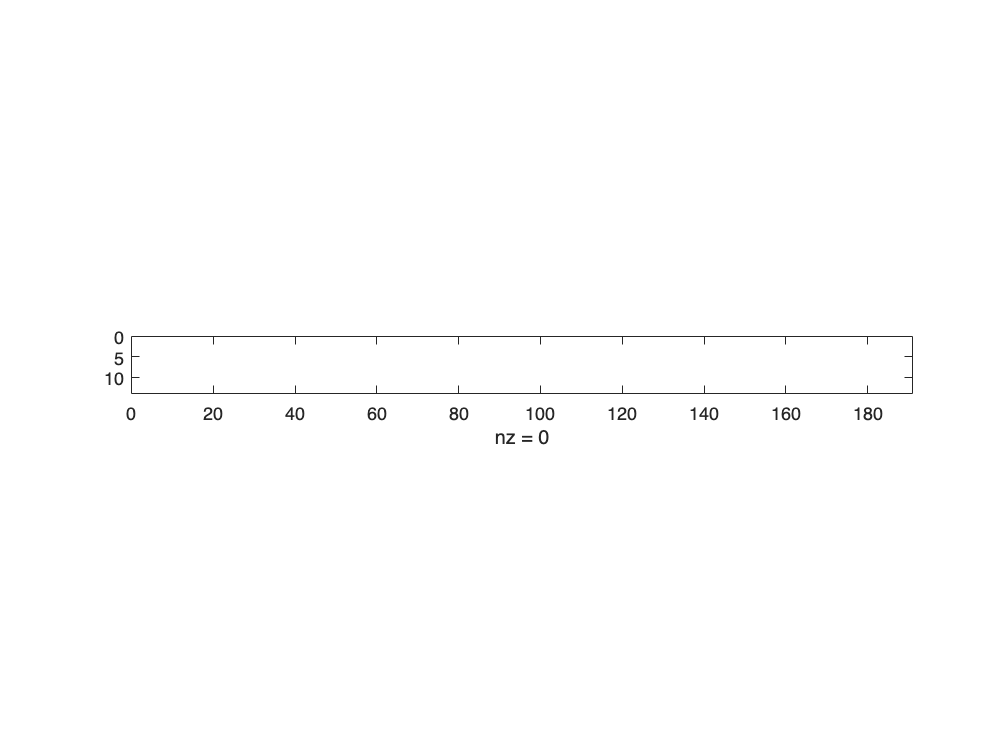

spy(transpose(isnan(table2array(SIG_prep_TT))))

### 2.3 Smooth Variables


% Smoothing State Variable
state_var1=dr1;
state_var2=dr2;

z1 = zeros(1,t_);
z2 = zeros(1,t_);

************************************************************************************************************#

************************************************************************************************************#

windowSize = 3;
test_EWMA = movavg(SIG_prep_TT, 'exponential', windowSize);

% Plot all asset normalised TRIs on a single plot
plot(test_EWMA.Time, table2array(test_EWMA));
ylabel("Signals test_EWMA");
xlabel("Time");
title("Monthly Normalised State Signals");
% include the legend
legend(SIG_PlotNames,Location="northwest");
test_EWMA_plot = gca;
hold off;

% Divide each element in each column of x by the first element of that column
SIG_prep_TT_normalised_array = table2array(SIG_prep_TT) ./ table2array(repmat(SIG_prep_TT(1,:),height(SIG_prep_TT),1));

% Convert the normalised array back to a timetable with the same timestamps as x
SIG_prep_TT_normalised = array2timetable(SIG_prep_TT_normalised_array, 'RowTimes', SIG_prep_TT.Dates);

% Copy the column names from x to x_normalised
SIG_prep_TT_normalised.Properties.VariableNames = SIG_prep_TT.Properties.VariableNames;

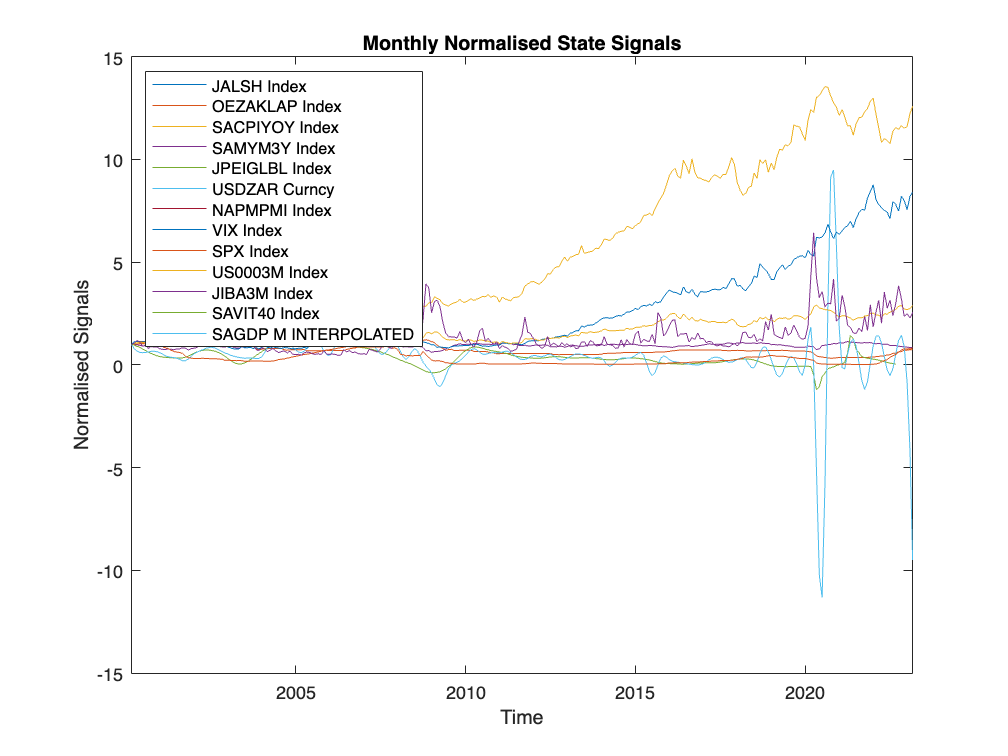

% Plot all asset normalised TRIs on a single plot
plot(SIG_prep_TT_normalised.Time, table2array(SIG_prep_TT_normalised));
ylabel("Normalised Signals");
xlabel("Time");
title("Monthly Normalised State Signals");
% include the legend
legend(SIG_PlotNames,Location="northwest");

SIG_norm_plot = gca;
hold off;

**Export Normalized Asset Class Wealth Series From TRIs Data plot**

exportName = 'SIG_norm_plot.pdf';
exportgraphics(SIG_norm_plot,fullfile(imageExportpath,exportName),'Resolution',300);

#### **SAVE Log Diff Returns Datasets:**

**TO DO: Use data_cleaning_001 to auto assign date range to file names (will code later)**

% % Convert the start and end dates to strings in the desired format (YYYYMMDD)
% startDateStr = datestr(ASSETCL_log_diff.Properties.StartTime, 'yyyymmdd');
% endDateStr = datestr(ASSETCL_log_diff.Properties.EndDate, 'yyyymmdd');
% 
% % Generate the file name
% fileName = sprintf('DATA-PROCESSED-INVARIANT-LOGDIFRETURNS-M-TTABLE-%s-%s.mat', startDateStr, endDateStr);
% 
% % Save the timetable object using the generated file name
% % save(fileName, 'timetableObj');

% 
exportName = 'DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat';
save(fullfile(dataExportpath,exportName),'ASSETCL_log_diff');

### 2.4 Check for normal distribution of returns 

Plot PP and QQ-plots to see if log diff data is roughly normally distributed

probplot(table2array(ASSETCL_log_diff));
legend(SIG_PlotNames,Location="northwest");
ASSETCL_logDifRet_PP_plot = gca;
hold off;

**Export PP plot of ASSET Class log diff returns**

exportName = 'ASSETCL_logDifRet_PP_plot.pdf';
exportgraphics(ASSETCL_logDifRet_PP_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

qqplot(table2array(ASSETCL_log_diff));
ylabel("Quantiles of Log Diff Returns")

title("QQ Plot of Log Difference Returns of Assets vs Standard Normal")
legend(SIG_PlotNames,Location="northwest");
ASSETCL_logDifRet_QQ_plot = gca;
hold off;

**Export QQ plot of ASSET Class log diff returns**

exportName = 'ASSETCL_logDifRet_QQ_plot.pdf';
exportgraphics(ASSETCL_logDifRet_QQ_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### 2.5 Check log diff returns are IID 

Need to be IID to be able to use as a invariant in HS-FP. Plot a scatter plot of the variable vs its own lag. Need to see the points are random and resemble roughly a circle 

% Get the variable names 
varNames = ASSETCL_log_diff.Properties.VariableNames;

% Create fig
figure;
% plot grid 
numRows = 3;
numCols = 2;

% Colour palette: Hexadecimal Colour Codes
colours = [0.3010 0.7450 0.9330; % blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880]; % green

% Loop over each variable
for i = 1:length(varNames)
    % Get the current and lagged version
    current_var = ASSETCL_log_diff.(varNames{i});
    current_lag = lagmatrix(current_var, 1);
    
    % Create scatter plot of current_var and current_lag
    subplot(numRows, numCols, i);
    scatter(current_lag,current_var, '.', 'MarkerEdgeColor', colours(i,:), ...
        'MarkerFaceColor', colors(i,:));
    
    % Set the title & axis labels of subplots
    title(SIG_PlotNames{i});
    ylabel(SIG_PlotNames{i});
    xlabel(strcat(SIG_PlotNames{i}, " lagged by 1"));

    % Make the x, y axes equal in length
    axis equal;
end

% Export the fig as a PDF
ASSETCL_logDifRet_Lag_Scatterplot = gcf;
hold off

**Export log dif returns against its lag plot of ASSET **

exportName = 'ASSETCL_logDifRet_Lag_Scatterplot.pdf';
exportgraphics(ASSETCL_logDifRet_Lag_Scatterplot,fullfile(imageExportpath,exportName),'Resolution',300);

- We need **risk drivers** to be **homogenous** over time but don't need to be iid.

- **Invariants** need to be **iid** across time, *however, * weaker assumption of **ergodicity** will suffice (and check stationarity)

*"If the idea is that one wants to predict the trend of the time series into the future using extrapolation of the historical time series, the time series needs to be stationary and ergodic." - From proposal *

Condition a.) of risk drivers 'the risk driver Y_t needs to completely specify the security price at any given time along with the security t&cs. However, if we have Stock prices (p) we know that prices are non-homogenous e.g. in the fixed income field, prices converge to the face value of zero coupon bonds as maturity approaches.

**Test for 1-2:**

**1. Test for homogeneity**

see: https://www.xlstat.com/en/solutions/features/homogeneity-tests-for-time-series#:~:text=What%20are%20homogeneity%20tests%20for,at%20which%20a%20change%20occurs.

**2. Test for iid, ergodicity and stationarity: **

IID: Scatter plot of compound returns log(S_t+1/ S_t) if is circular the variable will be a candidate for an invariant. 

Ergodicity: 

Test for stationarity using the augmented-dickey-fuller (ADF) test below indicates that we should not reject the H0 and that the series is a unit root process. Therefore the ALSI TRI is **nonstationary**. 

Therefore we need to adapt P to satisfy condition a.). The log price series is homogenous 

Test for stationarity using the augmented-dickey-fuller (ADF) test below indicates that we should not reject the H0 and that the series is a unit root process. Therefore the ALSI TRI is **nonstationary**. 

adftest(SIG_aligned_dataTable2lag.("JALSHTR Index"))

plot(SIG_aligned_dataTable2lag.("JALSHTR Index"));
title('Simulated Time Series')
xlabel('t')
ylabel('ALSITR')
close all

subplot(2,1,1)
autocorr(SIG_aligned_dataTable2lag.("JALSHTR Index"))
subplot(2,1,2)
parcorr(SIG_aligned_dataTable2lag.("JALSHTR Index"))
close all